# Triangulate a scene point given two calibrations of a camera

After having calibrated a camera using two images, we can now triangulate scene points 

addpath('../0.utils');

% load images and calibrations
calib_results_folder = '../0.calib_results';
calib_results_files = {'calib-cube-img_1.mat', 'calib-cube-img_2.mat', 'calib-cube-img_3.mat'};

% calculate grid dimension ...
n_cameras = length(calib_results_files);
if n_cameras <= 3
    grid_dim = [1, n_cameras];
else
    grid_col = ceil(sqrt(n_cameras));
    grid_dim = [ceil(n_cameras / grid_col), grid_col];
    clear grid_col;
end

% ... and plot the images
cameras = cell([1,n_cameras]);
for i=1:n_cameras
    % load camera
    cameras{i} = load(fullfile(calib_results_folder, calib_results_files{i}));
    % show image
    [~,name,~] = fileparts(calib_results_files{i});
    name = strsplit(name,'-');
    
    % store subplot handles for later use
    handles.axes(i) = subplot(grid_dim(1), grid_dim(2), i);
    imshow(cameras{i}.image), hold on;
    set(gcf,'Visible','on');  % with this the live script will show an external figure
    
    title(name{3});
end

clear name calib_results_folder calib_results_files grid_dim i;

Reproject calibration points

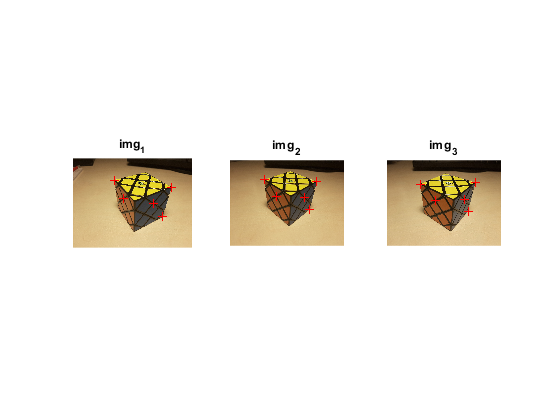

points = [2,3,5,7,8];
n_points = length(points);

P = zeros(3,4,n_cameras);
m = zeros(3,n_points,n_cameras);
for i=1:n_cameras
    P(:,:,i) = cameras{i}.P;
    % get pixel in each image corresponding to the same scene point
    m(:,:,i) = cameras{i}.m(:,points);
    hold on, handles.points(i) = scatter(handles.axes(i), m(1,:,i), m(2,:,i), '+r');
end

## Triangulation

Using the all the image points (just the calibration's ones) and the PPMs, triangulate the original (calibration) scene points and then reproject them onto the images to show the results. Here just two images are needed, but the script works with as many as you want, for better results.

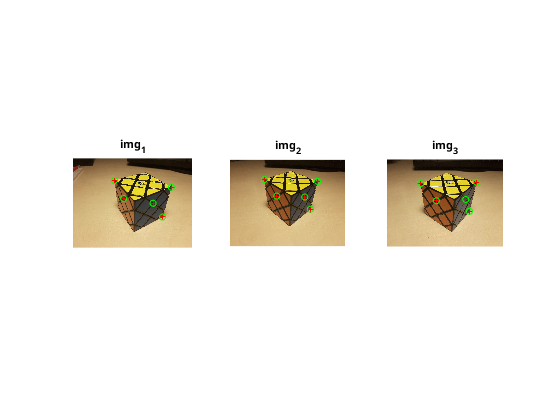

M = triangulate(P, m);

% replot the triangulated scene point onto the images
for i=1:n_cameras
    m_reproj = project(P(:,:,i), M);
    hold on, handles.reproj(i) = scatter(handles.axes(i), m_reproj(1,:), m_reproj(2,:), 'og');
end

clear i points P m m_reproj n_points n_cameras cameras handles;